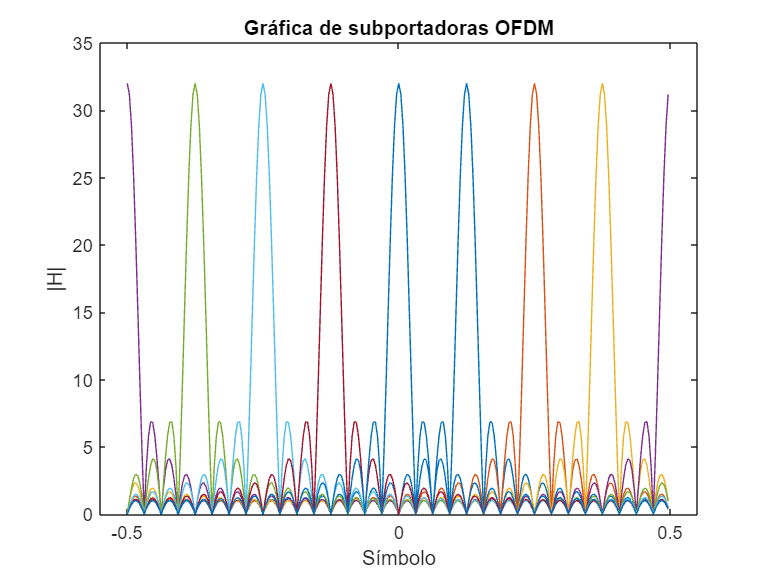

N=256;
T=32;
noofcarriers=floor(N/T);
for n=1:T
    for k=1:noofcarriers
        g(k,n)=exp(1i*2*pi*k*n/noofcarriers);
    end
end

for k=1:noofcarriers
    X(k,:)=abs(fft(g(k,:),N));
    X(k,:)=fftshift(X(k,:));
    f=(-N/2:N/2-1)/N;
    plot(f,X(k,:));
    xlim([-0.55 0.55])
    hold all;  
    title('Gráfica de subportadoras OFDM')
    xlabel('Símbolo')
    ylabel('|H|')
end